# Continuous time temperature-controlled 3 tank system

**sharing on inlet flow using on-off logical control modelled with the hybrid dmss class.**

[Open Live Script in Matlab](matlab:open('continuousThreeTanksDemo.mlx'))

clear, close all

## **Model creation**

The system is illustrated in figure 1. It consist of 3 water tanks sharing one inlet flow u2. The water tanks transfer heat between each other, as well as losing heat to the environment with the ambient temperature u1. If multiple valves (z1, z3 and z5) are opened at the same time the inlet flow will be shared uniformly between those. The control is designed to maintain the temperatures of the tanks (x1, x2 and x3) between lower (u3, u5 and u7) and upper bounds (u4, u6 and u8). There is one 2-Point controller per valve/tank.

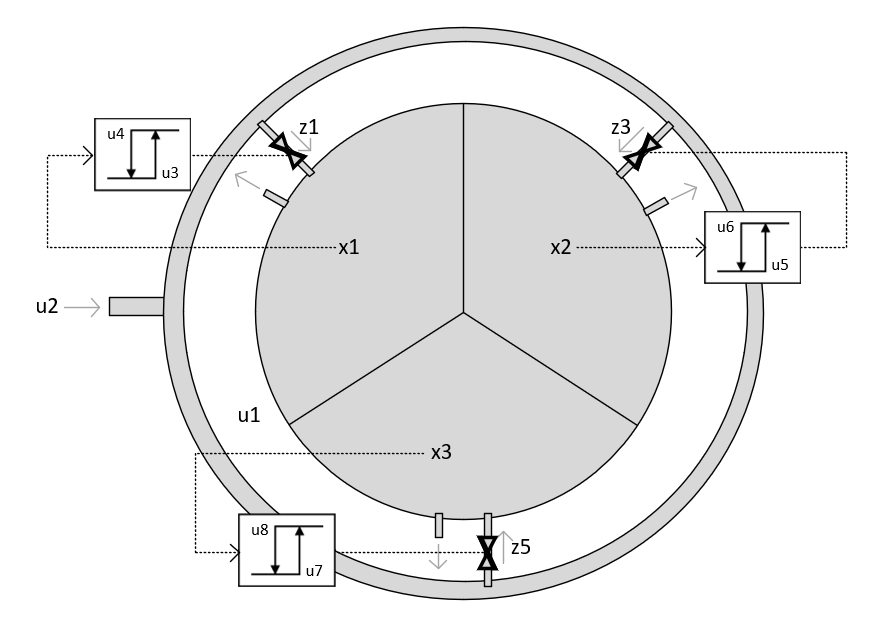

**Figure 1: Illustration of the temperature-controlled 3 tank system.**

The system can be described by the following difference equations and inequality constraints:

eq = {"m*cp*dx1 = k0A0*(u1-x1) + kinAin*(x2-x1) + kinAin*(x3-x1) + z1/y1*(u2-x1)*cp*fv";...
    "m*cp*dx2 = k0A0*(u1-x2) + kinAin*(x1-x2) + kinAin*(x3-x2) + z3/y1*(u2-x2)*cp*fv";...
    "m*cp*dx3 = k0A0*(u1-x3) + kinAin*(x1-x3) + kinAin*(x2-x3) + z5/y1*(u2-x3)*cp*fv";...
    "y1 = z1+z3+z5+(1-z1)*(1-z3)*(1-z5)";...
    "0 >= (u3-x1)*(1-z1+z2)";...
    "0 >= (u5-x2)*(1-z3+z4)";...
    "0 >= (u7-x3)*(1-z5+z6)";...
    "0 >= (x1-u4)*(1-z2+z1)";...
    "0 >= (x2-u6)*(1-z4+z3)";...
    "0 >= (x3-u8)*(1-z6+z5)"};

where the first three equations represent the dynamic energy balance of the three water tanks, the fourth equation calculates the share of water flow each tank with an active valve is getting and the inequlities represent the activation of the upper and lower bounds.

The set of equations and inequalities can be transformed into a dmss model by

ts = 0;
hybrid3TankSys = sym2dmss(eq, ts, ["dx", "x", "u", "y", "z"]);

Reduced by 23 column(s) and 0 equation(s) with trivial Reduction due to duplications.


with a time step size of 0.1 seconds. The set of equations and inequalities can be viewed:

disp(hybrid3TankSys.symbolicEquations)

$$\left(\begin{array}{c} x_{1}\,y_{1}\,\left({\mathrm{k0A}}_{0}+2\,\mathrm{kinAin}\right)-\mathrm{kinAin}\,x_{2}\,y_{1}-\mathrm{kinAin}\,x_{3}\,y_{1}-{\mathrm{k0A}}_{0}\,u_{1}\,y_{1}-\mathrm{cp}\,\mathrm{fv}\,u_{2}\,z_{1}+\mathrm{cp}\,\mathrm{fv}\,x_{1}\,z_{1}+\mathrm{cp}\,m\,{\mathrm{xp}}_{1}\,y_{1}=0\\ x_{2}\,y_{1}\,\left({\mathrm{k0A}}_{0}+2\,\mathrm{kinAin}\right)-\mathrm{kinAin}\,x_{1}\,y_{1}-\mathrm{kinAin}\,x_{3}\,y_{1}-{\mathrm{k0A}}_{0}\,u_{1}\,y_{1}-\mathrm{cp}\,\mathrm{fv}\,u_{2}\,z_{3}+\mathrm{cp}\,\mathrm{fv}\,x_{2}\,z_{3}+\mathrm{cp}\,m\,{\mathrm{xp}}_{2}\,y_{1}=0\\ x_{3}\,y_{1}\,\left({\mathrm{k0A}}_{0}+2\,\mathrm{kinAin}\right)-\mathrm{kinAin}\,x_{1}\,y_{1}-\mathrm{kinAin}\,x_{2}\,y_{1}-{\mathrm{k0A}}_{0}\,u_{1}\,y_{1}-\mathrm{cp}\,\mathrm{fv}\,u_{2}\,z_{5}+\mathrm{cp}\,\mathrm{fv}\,x_{3}\,z_{5}+\mathrm{cp}\,m\,{\mathrm{xp}}_{3}\,y_{1}=0\\ y_{1}-z_{1}\,z_{3}-z_{1}\,z_{5}-z_{3}\,z_{5}+z_{1}\,z_{3}\,z_{5}-1=0\\ u_{3}-x_{1}-u_{3}\,z_{1}+u_{3}\,z_{2}+x_{1}\,z_{1}-x_{1}\,z_{2}\leq 0\\ u_{5}-x_{2}-u_{5}\,z_{3}+u_{5}\,z_{4}+x_{2}\,z_{3}-x_{2}\,z_{4}\leq 0\\ u_{7}-x_{3}-u_{7}\,z_{5}+u_{7}\,z_{6}+x_{3}\,z_{5}-x_{3}\,z_{6}\leq 0\\ x_{1}-u_{4}-u_{4}\,z_{1}+u_{4}\,z_{2}+x_{1}\,z_{1}-x_{1}\,z_{2}\leq 0\\ x_{2}-u_{6}-u_{6}\,z_{3}+u_{6}\,z_{4}+x_{2}\,z_{3}-x_{2}\,z_{4}\leq 0\\ x_{3}-u_{8}-u_{8}\,z_{5}+u_{8}\,z_{6}+x_{3}\,z_{5}-x_{3}\,z_{6}\leq 0 \end{array}\right)$$

To simulate the system the symbolic parameters must be replaced by numeric values

m = 5;
cp = 4200;
k0A0 =  250* (0.5*1);
kinAin =  250* (0.5*1);
fv = 0.09;

symbolicParameters = [sym("m") sym("cp") sym("fv") sym("ts") sym("k0A0") sym("kinAin")];
numericParameters = [m cp fv ts k0A0 kinAin];
hybrid3TankSys = hybrid3TankSys.replaceSymbolicParameters(symbolicParameters, numericParameters);

## Simulation

For simulation the initial states and input signals have to be defined

x0 = [32, 30, 40];
t = 0:1000;
u = [0, 80, 30, 40, 25, 35, 35, 45].*ones([length(t), hybrid3TankSys.m]);

which are held constant for this example.

### Sparsity pattern analysis

Simulation can be performed by using the dmsim class, with by default using a equation reordering algorithm and identification of sub-problems and explicit solvable equations by sparsity pattern analysis.

The sparsity pattern can be calculated and viewed by the following procedure (also automaticly computed inside the simulation routine).

The sparsity pattern is calculated by

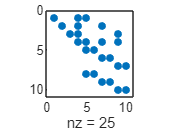

I = hybrid3TankSys.incidenceMatrix;
I = [I.equality.stateDerivative, I.equality.algebraic, I.equality.boolean;...
    I.inequality.stateDerivative, I.inequality.algebraic, I.inequality.boolean];
f1 = figure();
f1.Position(3:4) = [140 105];
spy(I)

and resorted using the Dulmage-Mendelsohn decomposition into a block lower triangular representation:

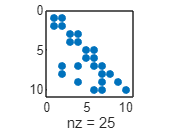

I = hybrid3TankSys.orderIncidenceMatrix(I);
f2 = figure();
f2.Position(3:4) = [140 105];
spy(I)

### Simulation with and without sparsity pattern analysis algorithm

Simulation time can be compared with and without using the sparsity pattern analysis algorithm: 

tic
result = dmsim(hybrid3TankSys, x0, [], [], t, u);
time = toc()

time = 1.9951


% opt.equationReordering = false;
% tic
% resultOff = dmsim(hybrid3TankSys, x0, [], t, u, opt);
% timeOff = toc()

The simulation times per time step are:

disp(time/length(t))

    0.0020



% disp(timeOff/length(t))

### Simulation results

The simulated temperatures as well as the binary valve signals (with an according time signal) can be accessed via the state property of the simulation object and can be plotted by

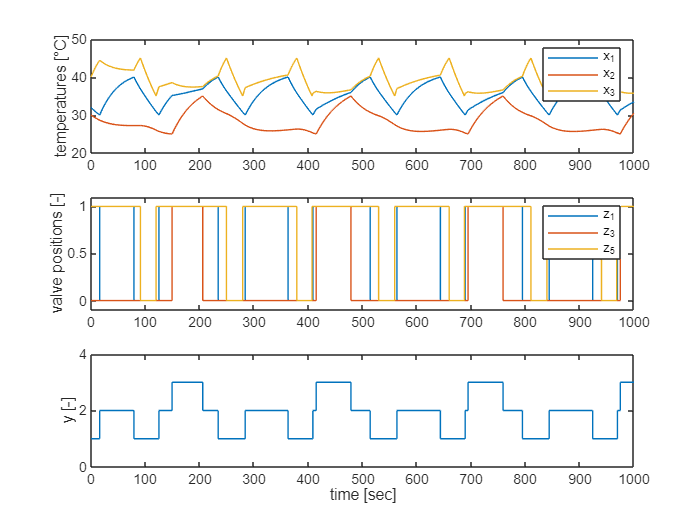

figure()
subplot(3,1,1)
plot(result.tsim, result.x)
hold on
legend(["x_1", "x_2", "x_3"])
ylabel('temperatures [°C]')
hold off

subplot(3,1,2)
plot(result.zt, result.z(:,1), '-')
hold on
plot(result.zt, result.z(:,3), '-')
plot(result.zt, result.z(:,5), '-')
ylabel('valve positions [-]')
legend(["z_1", "z_3", "z_5"])
axis([0 result.tsim(end) -0.1 1.1])
hold off

subplot(3,1,3)
plot(result.tsim, result.y(:,1))
hold on
ylabel('y [-]')
xlabel('time [sec]')
axis([0 result.tsim(end) 0 4])
hold off

With the simulated state signals the phase diagram can be plotted, revealing a period-2 orbit

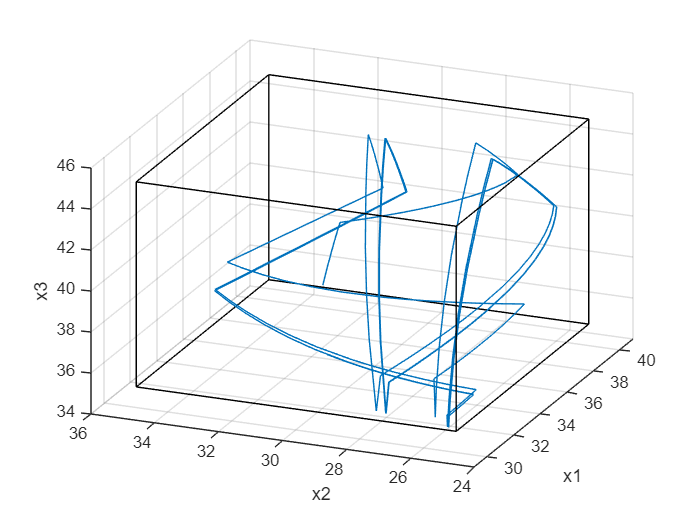

figure()
plot3(result.x(:,1), result.x(:,2), result.x(:,3))
hold on
surf([u(1,3) u(1,4)], [u(1,5), u(1,6)], [u(1,7) u(1,7); u(1,7) u(1,7)], 'EdgeColor','black', 'FaceColor', 'none'); %'EdgeColor','none', 'FaceAlpha', 0.1, 'FaceColor', 'red')
surf([u(1,3) u(1,4)], [u(1,5), u(1,6)], [u(1,8) u(1,8); u(1,8) u(1,8)], 'EdgeColor','black', 'FaceColor', 'none');%'EdgeColor','none', 'FaceAlpha', 0.1, 'FaceColor', 'red')
surf([u(1,3) u(1,3)], [u(1,5), u(1,6)], [u(1,7) u(1,8); u(1,7) u(1,8)], 'EdgeColor','black', 'FaceColor', 'none');%'EdgeColor','none', 'FaceAlpha', 0.1, 'FaceColor', 'black')
surf([u(1,4) u(1,4)], [u(1,5), u(1,6)], [u(1,7) u(1,8); u(1,7) u(1,8)], 'EdgeColor','black', 'FaceColor', 'none');%'EdgeColor','none', 'FaceAlpha', 0.1, 'FaceColor', 'black')
surf([u(1,3) u(1,4)], [u(1,5), u(1,5)], [u(1,7) u(1,7); u(1,8) u(1,8)], 'EdgeColor','black', 'FaceColor', 'none');%'EdgeColor','none', 'FaceAlpha', 0.1, 'FaceColor', 'magenta')
surf([u(1,3) u(1,4)], [u(1,6), u(1,6)], [u(1,7) u(1,7); u(1,8) u(1,8)], 'EdgeColor','black', 'FaceColor', 'none');%'EdgeColor','none', 'FaceAlpha', 0.1, 'FaceColor', 'magenta')
grid on
xlabel("x1")
ylabel("x2")
zlabel("x3")
axis([29 41 24 36 34 46])
view([-67.5,29.5])
hold off

## References

[1] T. Warnecke and G. Lichtenberg, "Approach for the mode switching problemin piecewise smooth implicit multilinear IVPs", unpublished.

Author(s): Torben Warnecke